# Problem 3

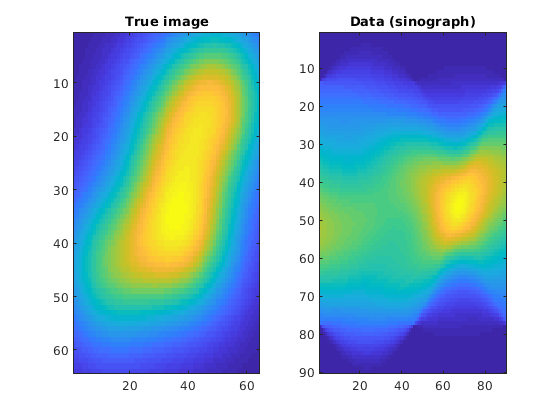

clc;
clear;
close all;
rng('default');

N = 64;          % Image is N-by-N pixels
theta = 0:2:178; % projection angles
p = 90;          % Number of rays for each angle

% Assemble the X-ray tomography matrix, the true data, and true image
K = paralleltomo(N, theta, p);

% Generate synthetic data
m_true = phantomgallery('smooth', N);
m_true = m_true(:);
d = K*m_true;

figure;
subplot(121);
imagesc(reshape(m_true, N, N));
title('True image');
subplot(122);
imagesc(reshape(d, p, length(theta)));
title('Data (sinograph)');

% Remove possibly 0 rows from K, and d
[K, d] = purge_rows(K, d);

% Rescale K, and d so that the l2 norm of each row is 1
s = sqrt(sum(K.*K, 2));
K = spdiags(1./s,0)*K;
d = spdiags(1./s,0)*d;

## A) Reconstruct m using EM. Report D_KL(d || K*m) and ||m - m_true||

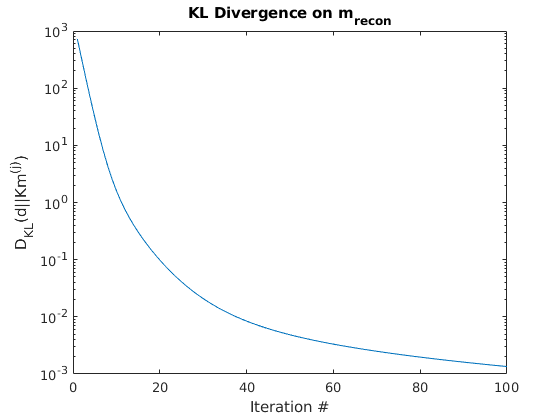

% initialize variables
iterations = 100;
m_recon = ones(size(m_true,1),101);
KL_divergence = zeros(iterations,1);
norm_error = zeros(iterations,1); 
sp = sum(K,1);
SinvKT = diag(sp.^-1)*K';

% run EM algorithm
for i=1:iterations
    m_recon(:,i+1) = m_recon(:,i).*SinvKT*(d./(K*m_recon(:,i)));
    KL_divergence(i) = sum(d.*log(d./(K*m_recon(:,i+1))),1);
    norm_error(i) = norm(m_true - m_recon(:,i+1));
end
% plot KL Divergence and norm error
figure;
semilogy(1:100,KL_divergence); title('KL Divergence on m_{recon}');
ylabel('D_{KL}(d||Km^{(j)})'); xlabel('Iteration #');

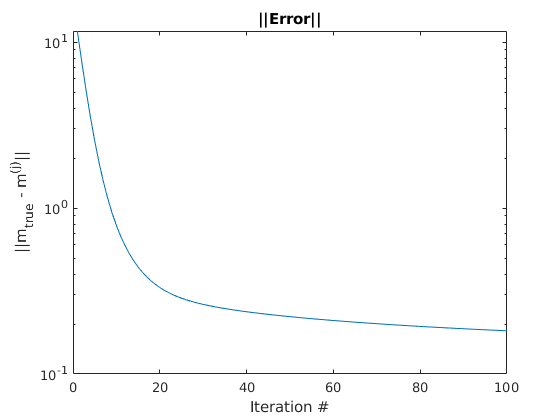

figure;
semilogy(1:100,norm_error); title('||Error||');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');

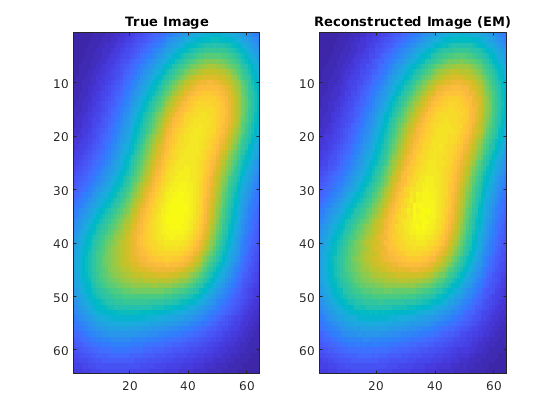

% plot true image vs. reconstructed
figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(m_recon(:,101), N, N)); title('Reconstructed Image (EM)');

## B) Consider the noisy data case, i.e d is a realization of a Poisson distributed random vector. Design an appropriate stopping criterion for EM and reconstruct m

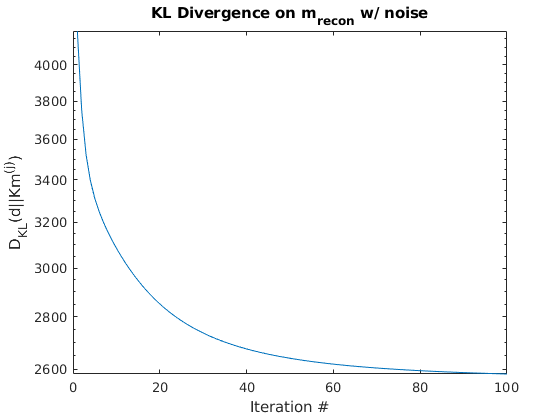

% add poisson noise to data
dn = poissrnd(K*m_true);

% initialize variables
iterations = 100;
mn_recon = ones(size(m_true,1),101);
KL_divergence_n = zeros(iterations,1);
norm_error_n = zeros(iterations,1);

% run EM algorithm
for i=1:iterations
    mn_recon(:,i+1) = mn_recon(:,i).*SinvKT*(dn./(K*mn_recon(:,i)));
    KL_sum = dn.*log(dn./(K*mn_recon(:,i+1))); KL_sum_rn = KL_sum(~isnan(KL_sum)); % remove nans
    KL_divergence_n(i) = sum(KL_sum_rn,1);
    norm_error_n(i) = norm(m_true - mn_recon(:,i+1));
end
% plot KL Divergence and norm error
figure;
semilogy(1:100,KL_divergence_n); title('KL Divergence on m_{recon} w/ noise');
ylabel('D_{KL}(d||Km^{(j)})'); xlabel('Iteration #');

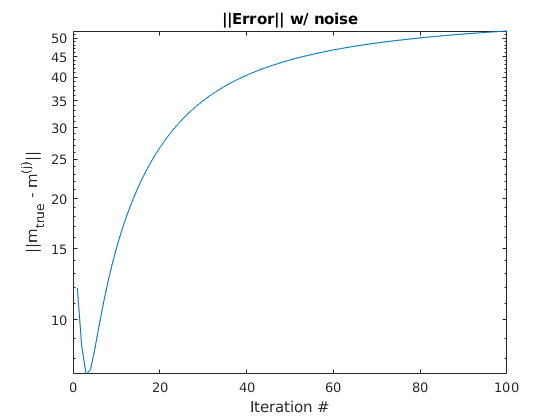

figure;
semilogy(1:100,norm_error_n); title('||Error|| w/ noise');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');

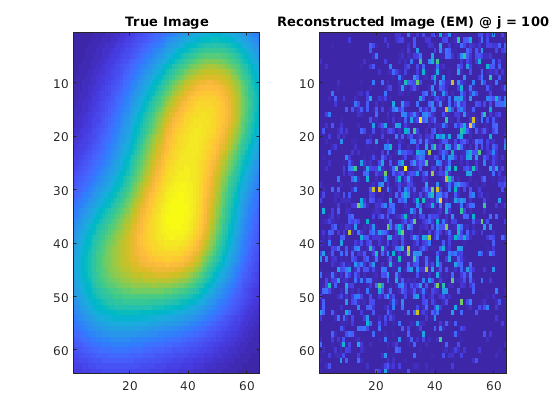

% plot true image vs. reconstructed (at last iteration)
figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(mn_recon(:,101), N, N)); title('Reconstructed Image (EM) @ j = 100');

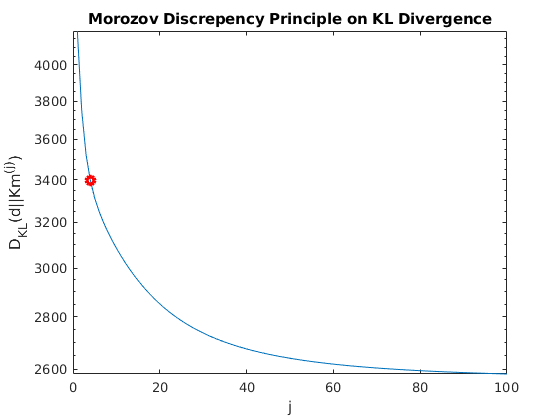

% Use morozov discrepency with respect to KL Divergence

% estimate the "noise norm" through KL divergence for K*m_true
KL_sum_nn = dn.*log(dn./(K*m_true)); KL_sum_rn_nn = KL_sum_nn(~isnan(KL_sum_nn)); % remove nans
delta = sum(KL_sum_rn_nn,1);

% find morozov iteration through bisection method
a = 100;
b = 1;
KLD_a = KL_divergence_n(a);
KLD_b = KL_divergence_n(b);
iterations = 20;
for i=1:iterations
    % find midpoint
    midpoint = round((a + b)/2);
    
    % get KL divergence at midpoint
    KLD_mid = KL_divergence_n(midpoint);
    
    % check current intervals and assign new intervals
    if KLD_a <= delta && delta <= KLD_mid
       b = midpoint;
        KLD_b = KL_divergence_n(b);
    elseif KLD_mid <= delta && delta <= KLD_b
        a = midpoint;
        KLD_a = KL_divergence_n(a);
    else
        error(['Optimal j outside bounds! \' ...
            'Increase initial j search range.'])
    end
end
% get optimal morozov j and resid
j_opt = round((a + b)/2);
KLD_opt = KL_divergence_n(j_opt);

% plot morozov discrepency
figure;
semilogy(1:100,KL_divergence_n); hold on;
semilogy(j_opt, KLD_opt, 'ro', 'Linewidth', 3);
title('Morozov Discrepency Principle on KL Divergence');
xlabel('j'); ylabel('D_{KL}(d||Km^{(j)})');
hold off;

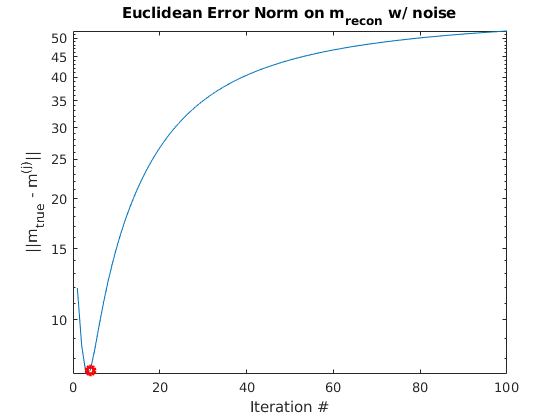

figure;
semilogy(1:100,norm_error_n); hold on;
semilogy(j_opt,norm_error_n(j_opt),'ro','Linewidth',3);
title('Euclidean Error Norm on m_{recon} w/ noise');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');
hold off;

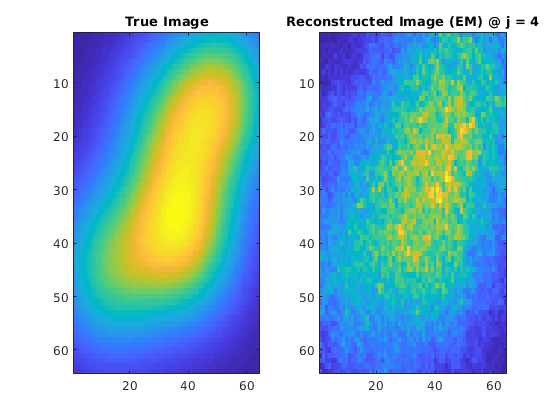

figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(mn_recon(:,j_opt), N, N));
title(['Reconstructed Image (EM) @ j = ' num2str(j_opt)]);